# Hands-On: Power Spectra & Spectral Factorization

## Spectral Factorization

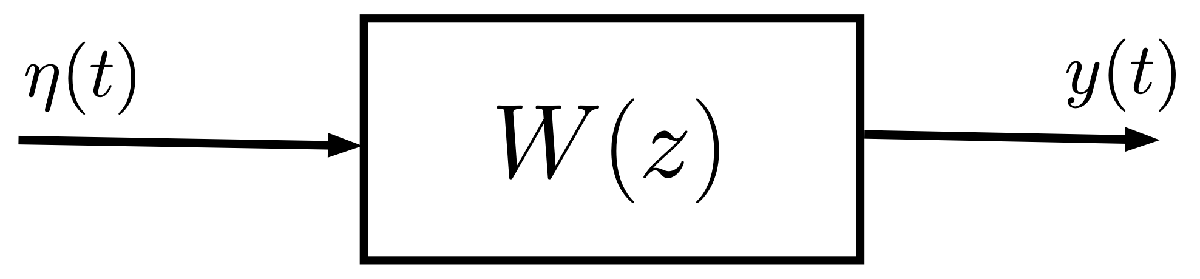

A stationary stochastic process $y(t)$ has the power spectrum


$$\Gamma_y(\omega) = \displaystyle \frac{50}{29-20\,\cos (\omega)$$


Find the LTI filter $W(z)$ that creates $y(t)$ by filtering the white noise $\eta(t)$, and find the variance of the white noise $\sigma^2_{\eta}$.

**Hint**: analyse and reuse the code in [this live script](matlab:open('./L8_SpectralFactorization.mlx')).

clear 
close all
clc


% put here your code

- Find the LTI filter $W(z)$ that creates $y(t)$ by filtering the white noise $\eta(t)$

syms omega
Gamma_y = 50 / (29 - 20*cos(omega))

$$Gamma\_y = -\frac{50}{20\,\cos\left(\omega \right)-29}$$

Having the power spectrum, we can calculate the variance of $y$ using $\sigma_{y}^2 = \displaystyle \frac{1}{2\, \pi} \int_{-\pi}^{+\pi} \, \Gamma_y(\omega) \,d\omega$ (anti-Fourier's transform)

sigma2_y =  ( (1/(2*pi))*int(Gamma_y,omega, [-pi,pi] ))

$$sigma2\_y = \frac{47784676160188825\,\pi }{63050394783186944}$$

sigma2_y_ALT =  double(sigma2_y)

sigma2_y_ALT =    2.380952380952381


Sigma2Y = sym(sigma2_y_ALT)

$$Sigma2Y = \frac{50}{21}$$

The next step is to convert $\Gamma_y$ into $W(z)$, to do this we have to:

- Rewrite $\Gamma_y$ using the exponential notation

- Replace exponentials with z and get $\Phi_Z$

- Solve $\Phi_Z = W(z) * W(\frac{1}{z}) * \sigma^2_{\eta}$

Gamma_y = simplify(rewrite(Gamma_y, "exp"))

$$Gamma\_y = -\frac{50}{10\,{\mathrm{e}}^{-\omega \,\mathrm{i}}+10\,{\mathrm{e}}^{\omega \,\mathrm{i}}-29}$$

syms z;
PhiZ = subs(Gamma_y, exp(1i*omega), z)

$$PhiZ = -\frac{50}{10\,z+\frac{10}{z}-29}$$

So far the result is good, since the denominator can be rewritten factoring out $z + \frac{1}{z}$ 

In order to calculate the third point, we have to make use of the Spectral Factorization Theorem

#### The Spectral Factorization Theorem

Given a process with rational spectrum $\Phi(z)\,$, there exists one and only one representation of the process as the output of an LTI system driven by a white process $\xi(\cdot)$ and with transfer function $W(z) = \frac{N(z)}{D(z)}$  if the following conditions are imposed on $W(z)\,$:

- $N(z)\,$ and $D(z)\,$ monic, co-prime and of the same degree;

- all roots of $N(z)\,$ (zeros of $W(z)\,$ ) have $\vert \,\cdot\,\vert \le 1\,$; 

- all roots of $D(z)\,$ (poles of $W(z)\,$ ) have $\vert \,\cdot\,\vert < 1\,$.


$$\Phi_{y}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\xi}(z) =  W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \lambda^2_{\xi}$$


In order to apply the "*Spectral Factorization Algorithm*" we have to  determine the coefficients of both the symmetric polynomials at the numerator and the denominator in the rational spectrum expression. 

A simple trick to obtain the needed polynomial coefficients is based on the symbolic variable substitution $\left(z+z^{-1}\right) \longrightarrow x$ into the expression of $\Phi(z)$

syms x
PhiX = subs(PhiZ,(z+z^(-1)), x) % the first step of the trick: substituting the expression

$$PhiX = -\frac{50}{10\,x-29}$$

% the second step of the trick: get numerator and denominator of the
% symbolic expression PhiX
[betaX, alphaX] = numden(PhiX)

$$betaX = -50$$

$$alphaX = 10\,x-29$$

Finally, extract the coefficient array from each polynomial, ordered from the highest to the lowest degree of the monomials in the instrumental variable $x$

betaPoly = sym2poly(betaX) % the coefficients of the numerator of the spectrum, as a symmetric polynomial

betaPoly =    -50


% betaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

alphaPoly = sym2poly(alphaX) % the coefficients of the denominator of the spectrum, as a symmetric polynomial

alphaPoly =     10   -29


% alphaPoly contains the floating-point description of the coefficients, 
% from the highest to the lowest degree monomial of the auxiliary variable x

Now we re ready to apply the *Spectral Factorization Algorithm*. 

#### The Spectral Factorization Algorithm: a Summary

Given the rational spectrum 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \displaystyle \frac{\displaystyle \sum_{k=-m}^{m}\, \beta_k\,z^k}{\displaystyle \sum_{k=-n}^{n}\,\alpha_k\,z^k}$$


with


$$\left\{
\begin{array}{lcl}
\alpha_p = \alpha_{-p} &\quad& p=-n\,,\,-n+1\,,\, \cdots ,\, n-1\,,\, n \\
\beta_q = \beta_{-q} &\quad& q=-m\,,\,-m+1\,,\, \cdots ,\, m-1\,,\, m \\
\alpha_n \ne 0 \,,\; \beta_m \ne 0 &\quad& \text{i.e. both polynomials are symmetric polynomials in $z$ and $z^{-1}$} \\
\Phi\left(e^{i\,\omega} \right) \ge 0 \; \forall \omega& \quad &\text{i.e. $\Phi(z)$ is a rational spectrum}
\end{array}
\right.$$


then there is only one factorization of the spectrum $\Phi(z)$ such that


$$\Phi(z) = \displaystyle \frac{C(z)}{A(z)} \cdot \frac{C\left(z^{-1}\right)}{A \left(z^{-1}\right)} \cdot r$$


with


$$\left\{
\begin{array}{rcl}
r &>& 0 \\
A(z) &=& 1+a_1\,z^{-1}+a_2\,z^{-2}+\cdots+a_n\,z^{-n} \quad \text{with } z_p: A(z_p) = 0 \,,\; \vert z_p \vert <1 \; \forall p \\
C(z) &=& 1+c_1\,z^{-1}+c_2\,z^{-2}+\cdots+c_m\,z^{-m} \quad \text{with } z_q: C(z_q) = 0 \,,\; \vert z_q \vert \le 1 \; \forall q 
\end{array}
\right.$$


**First step of the algorithm: **exploiting the fact that both $\alpha(z)$ and $\beta(z)$ are symmetric polynomials, factor both the polynomials 


$$\left\{
\begin{array}{rcl}
\alpha(z) &=& r_1\, A(z)\, A\left(z^{-1}\right) \\
\beta(z) & =& r_2\, C(z)\, C\left(z^{-1}\right)
\end{array}
\right.$$


where $r_1>0$, $r_2>0$ and the polynomials $A(z)$ and $C(z)$ are monic polynomials as defined above.

**Second step of the algorithm**: the spectral factorization of $\Phi(z)$ is 


$$\Phi(z) = \displaystyle \frac{\beta(z)}{\alpha(z)} = \left( \frac{r_2}{r_1} \right)\cdot \left[ \frac{C(z)}{A(z)} \right] \cdot \left[\frac{C\left(z^{-1}\right)}{A\left(z^{-1}\right)} \right] = r \cdot W(z) \cdot W\left(z^{-1}\right)$$


#### The Resulting Factorization

Given the description of both the polynomials $\beta(z)$ and $\alpha(z)$ as symmetric polynomials, we can obtain the spectral factorization simply using the live function `L8_spectrFactAlg()`

[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(betaPoly, alphaPoly)

r =      2


Cz_coeffs =      1


Az_coeffs =    1.000000000000000  -0.400000000000000


Now rewrite the result as symbolic rational function

% sort the display output of polynomial function in ascending order, i.e.
% according to the order of each monomial term
sympref('PolynomialDisplayStyle','ascend');

syms z1 % a trick to represent in a compact way 1/z

lambda2xi = sym(r) % the white noise spectrum

$$lambda2xi = 2$$

Az1 = poly2sym(fliplr(Az_coeffs), z1) % the polynomial A(z) 

$$Az1 = 1-\frac{2\,z_{1}}{5}$$

Az = subs(Az1,z1,z^(-1))

$$Az = 1-\frac{2}{5\,z}$$

Cz1 = poly2sym(fliplr(Cz_coeffs), z1) % the polynomial C(z) 

$$Cz1 = 1$$

Cz = subs(Cz1,z1,z^(-1))

$$Cz = 1$$

Wz = Cz1/Az1 % the LTI system transfer function as symbolic object

$$Wz = -\frac{1}{-1+\frac{2\,z_{1}}{5}}$$

W_z = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')